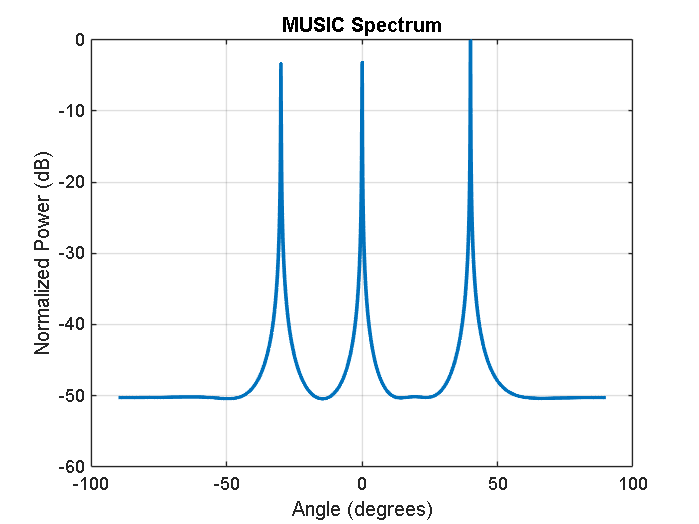

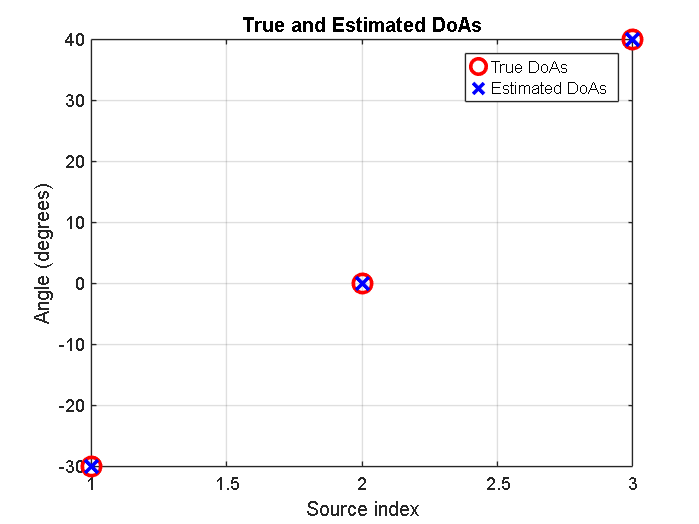

% Simulation parameters
M = 8;                      % Number of antennas
K = 3;                       % Number of sources (APs)
d = 0.0107 / 2;              % Distance between antennas (half-wavelength)
wavelength = 0.0107;         % Wavelength at 28 GHz (in meters)
SNR = 20;                    % Signal-to-noise ratio (dB)
fs = 1e6;  % Sampling frequency in Hz (e.g., 1 MHz, adjust as needed)


% True DoA angles
true_DoAs = [-30, 0, 40];    % True DoA angles (in degrees)

% Check if M >= K
if M < K
    error('Number of antennas must be greater than or equal to number of sources');
end

% Generate synthetic data
[x, A_true] = generate_synthetic_data(M, K, d, wavelength, true_DoAs, SNR);

% Apply the algorithm
doa_estimates = algo(x, M, K, d, wavelength);

% Plot the results
plot_results(x, A_true, doa_estimates, M, K, d, wavelength, true_DoAs);

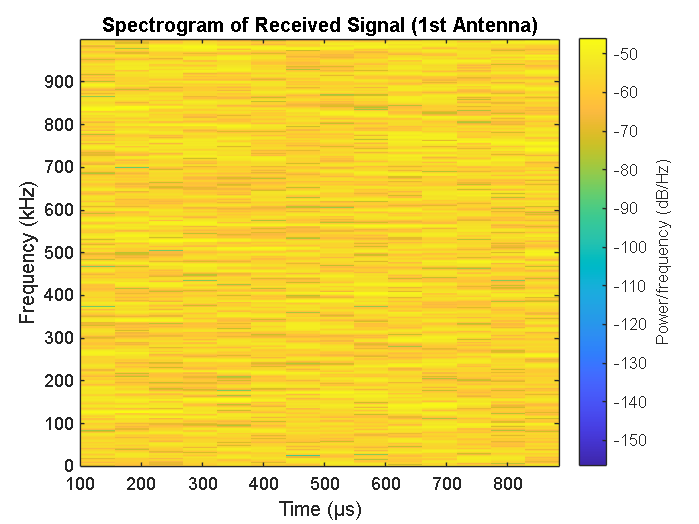


figure;
spectrogram(x(1,:), 256, 200, 512, fs, 'yaxis');
title('Spectrogram of Received Signal (1st Antenna)');



% Function to generate synthetic data
function [x, A] = generate_synthetic_data(M, K, d, wavelength, DoAs, SNR)
    N = 1000; % Number of samples
    fs = 1e6; % Sampling frequency (1 MHz)
    t = (0:N-1)/fs; % Time vector

    % Define Doppler shifts for each source (in Hz)
    doppler_shifts = [200, -150, 100]; % Example for 3 moving sources

    % Steering matrix
    A = exp(-1i*2*pi*d*(0:M-1)'*sind(DoAs)/wavelength); % M x K

    % Generate baseband signals with Doppler effect
    S = zeros(K, N);
    for k = 1:K
        S(k, :) = sqrt(0.5) * (randn(1, N) + 1i * randn(1, N)) ...
                  .* exp(1i*2*pi*doppler_shifts(k)*t); % Apply Doppler
    end

    % Noise
    noise_variance = 10^(-SNR/10) * trace(A * (S * S') * A') / (M * N);
    n = sqrt(noise_variance / 2) * (randn(M, N) + 1i * randn(M, N)); % M x N

    x = A * S + n; % M x N
end


% Algorithm function
function doa_estimates = algo(x, M, K, d, wavelength)
    % Compute the MUSIC spectrum
    theta = -90:0.1:90;
    [Vn, Pmusic] = compute_music_spectrum(x, M, K, d, wavelength, theta);

    % Find the initial estimates of DoAs
    [~, doa_indices] = sort(Pmusic, 'descend');

    % If more than K peaks are found, select the K largest ones
    if length(doa_indices) > K
        doa_indices = doa_indices(1:K);
    end

    initial_DoAs = theta(doa_indices);

    % Refine the DoAs using fminsearch
    doa_estimates = zeros(1, K);
    for i = 1:length(initial_DoAs)
        error_function = @(x) abs(1 / abs((a(x, d, M, wavelength)' * Vn) * (Vn' * a(x, d, M, wavelength))) - Pmusic(doa_indices(i)));
        doa_estimates(i) = fminsearch(error_function, initial_DoAs(i));
    end

    % If less than K estimates were found, fill the remaining ones with NaN
    if length(doa_estimates) < K
        doa_estimates = [doa_estimates, nan(1, K - length(doa_estimates))];
    end
end

% Function to compute steering vector
function a_vec = a(angle, d, M, wavelength)
    a_vec = exp(-1i*2*pi*d*(0:M-1)'*sind(angle)/wavelength);
end


% Function to compute the MUSIC spectrum
function [Vn, Pmusic] = compute_music_spectrum(x, M, K, d, wavelength, theta)
    Rxx = (x * x') / size(x, 2);
    [V, D] = eig(Rxx);
    [~, idx] = sort(diag(D), 'descend');
    V = V(:, idx);
    Vn = V(:, K+1:end);

    % Calculate the MUSIC spectrum
    Pmusic = arrayfun(@(angle) 1 / abs((a(angle, d, M, wavelength)' * Vn) * (Vn' * a(angle, d, M, wavelength))), theta);
end


% Function to plot the results
function plot_results(x, ~, doa_estimates, M, K, d, wavelength, true_DoAs)
    % Compute the MUSIC spectrum
    theta = -90:0.1:90;
    [~, Pmusic] = compute_music_spectrum(x, M, K, d, wavelength, theta);


    % Plot the MUSIC spectrum
    figure;
    plot(theta, 10 * log10(abs(Pmusic)/max(abs(Pmusic))), 'LineWidth', 2);
    xlabel('Angle (degrees)');
    ylabel('Normalized Power (dB)');
    title('MUSIC Spectrum');
    grid on;

    % Plot the true and estimated DoAs
    figure;
    plot(1:K, sort(true_DoAs), 'ro', 'LineWidth', 2, 'MarkerSize', 10, 'DisplayName', 'True DoAs');
    hold on;
    plot(1:K, sort(doa_estimates), 'bx', 'LineWidth', 2, 'MarkerSize', 10, 'DisplayName', 'Estimated DoAs');
    xlabel('Source index');
    ylabel('Angle (degrees)');
    title('True and Estimated DoAs');
    legend;
    grid on;
    hold off;
end